# Copyright of this code belongs to Dipankar Maity (dmaity@uncc.edu).

Do not distribute this code.

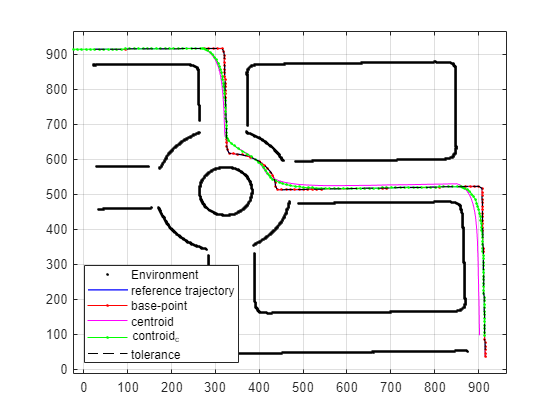

clear all 
% 'D' is the distance of the pen from the base of the robot
% 'k' is the control parameter
global D h k m;

down_sample_amount = 10;

% Circle
D = 50; k = 1; m = 1;h = .002; % m > 1
position = importdata("referencetrajectory.mat");
map = importdata("referencetrajectory_map_without.mat");



% plot(map(1,:), map(2,:),'.')

l = 1;
for i = 1:down_sample_amount:length(position)
    new_position(:,l) = position(:,i);
    l = l+1;
end
position = new_position;
     
state1(:,1) =[position(1,1)-D; position(2,1); 0];     
state(:,1) =[position(1,1)-D; position(2,1); 0];
xb(1) = state(1,1) + D*cos(state(3,1));
yb(1) = state(2,1) + D*sin(state(3,1));
theta(1) = state(3,1); 
  
  T = size(position,2)-1;
  t = 1:T;
  xVelocity = (position(1,t+1) - position(1,t))/h;
  yVelocity = (position(2,t+1) - position(2,t))/h;

for t =1 : T
    n1 = 0*randn(1);
    n2 = 0*randn(1);
    % x= current state
    x= [xb(t); yb(t); theta(t)];
    
    % controller returns the desired velocities
    [v, w] = controller(x, xVelocity(t), yVelocity(t),position(:,t));
    
    % use the dynamics with desired velocities to generate the velocities
    dot_x = dynamics(x,v,w,n1,n2);
    
     linear_vel(t) = v+n1;
     angular_vel(t) = w+n2;
     
    % integrate the position to get the new position
    xb(t+1) = xb(t) + dot_x(1)*h;
    yb(t+1) = yb(t) + dot_x(2)*h;
    theta(t+1) = theta(t) + dot_x(3)*h;
    
    % centroid dynamics
    state1(:,t+1) = state1(:,t) + h*[(v+n1)*cos(theta(t)); (v+n1)*sin(theta(t)); w+n2];
    state(:,t) = [xb(t); yb(t); theta(t)] - [D*cos(theta(t)); D*sin(theta(t)); 0];
    
end
E = position-[xb;yb];
for i = 1:length(position)
    E_norm(i) = norm(E(:,i));
end
base_point = [xb; yb; theta];



figure
plot(map(1,:), map(2,:)+20,'.','color','k')
hold on;
plot(position(1,:),position(2,:),'color','b','linewidth',1);
plot(xb, yb, '.-','color', 'r')
plot(state1(1,:), state1(2,:),'color', 'm');
plot(state(1,:), state(2,:),'.-','color','g'); 
[tolerance1, tolerance2] = plot_tolerance(position,max(E_norm));
grid on;
xlim([min(position(1,:))-D max(position(1,:))+D])
ylim([min(position(2,:))-D max(position(2,:))+D])
legend('Environment', 'reference trajectory', 'base-point', 'centroid', 'controid_c', 'tolerance',"location", 'southwest')
hold off

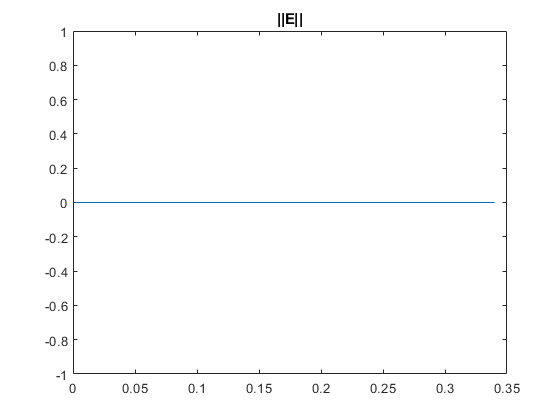




figure
plot([1:length(position)]*h,E_norm)
title('||E||')

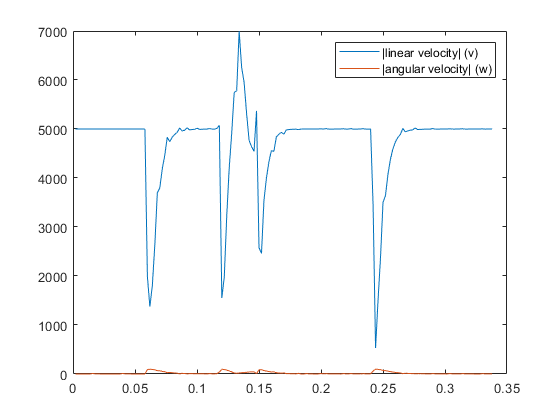


figure
plot([1:size(linear_vel,2)]*h, abs(linear_vel)); hold on
plot([1:size(angular_vel,2)]*h, abs(angular_vel));
legend('|linear velocity| (v)', '|angular velocity| (w)')


% save("tolerance1","tolerance1")
% save("tolerance2","tolerance2")
% save("road_error_centroid","state")
% save("road_error_base-point","base_point")

function [v, w] = controller(x, xVelocity, yVelocity,position)
global D k m
 

J = [cos(x(3)) -D*sin(x(3));
    sin(x(3))  D*cos(x(3)) ];
E = x(1:2,1)- [position(1); position(2)];

% if norm(E) > m
%         v_feedback = [xVelocity; yVelocity] - k*m/norm(E)*E;
%     else
    v_feedback = [xVelocity; yVelocity] - k*E;
% end

desired_control = (J)\v_feedback;

v = desired_control(1);
w = desired_control(2);

end

function dot_x = dynamics(x,v,w,n1,n2)
global D

M = [cos(x(3)) -D*sin(x(3));
     sin(x(3))  D*cos(x(3));
     0          1          ];

dot_x = M*[v+n1; w+n2];

end

function [tolerance1, tolerance2] = plot_tolerance(z,d) % function to plot tolerance
% initialize distances between edges of the tolerance line
s = [d; -d];   
for i = [1:length(z)-1]
  theta = atan2(z(2,i+1)-z(2,i),(z(1,i+1)-z(1,i)));
% calcualte 1x2 array with edge points
    x(:,i) = s*sin(theta) + z(1,i);
    y(:,i) = -s*cos(theta) + z(2,i);
  
    
end
tolerance1(1,:) = x(1,:);
tolerance1(2,:) = y(1,:);
tolerance2(1,:) = x(2,:);
tolerance2(2,:) = y(2,:);
plot(x(1,:),y(1,:),'--','color','k')
plot(x(2,:),y(2,:),'--','color','k')
end